# Denavit - Hartenberg Kinematics

## Direct Kinematics

clear; clc; close all;
syms(sym('q', [1 3]));

% DH parameters
D=[2 4 0]; A=[1.1 0 1.5]; T=[0 pi/2 -pi/2]; F=[+pi/2 -pi/2 -pi/2];
alpha=pi/6;
P3e=[0;0;0;1];

DHpar=[q1+T(1)  D(1)       A(1)   F(1)-alpha;
       T(2)     q2+D(2)    A(2)   F(2);
       q3+T(3)  D(3)       A(3)   F(3)];

% Define symbolic matrix
M03(q1,q2,q3) = DH_total_matrix(DHpar);

DHdirect = M03*P3e; % Direct kinematics function
DHdirect = matlabFunction(DHdirect,'Vars',[q1 q2 q3]);

% Position of the gripper in the reference system 0 at the initial conditions 
P0e_0=DHdirect(0,0,0)

P0e_0 =     1.1000
   -4.7631
    4.7500
    1.0000


### Workspace

% Joints variables 
nPoints=[30 5 15];
limits=[-pi pi 0 3 -pi*0.5 pi*0.5];
q1_inf = limits(1); q1_sup = limits(2); q1=linspace(q1_inf,q1_sup,nPoints(1));
q2_inf = limits(3); q2_sup = limits(4); q2=linspace(q2_inf,q2_sup,nPoints(2));
q3_inf = limits(5); q3_sup = limits(6); q3=linspace(q3_inf,q3_sup,nPoints(3));

Q = allCombinations(q1,q2,q3); % all possible combinations of joints variables
tic
for i=1:size(Q,1)
    P(i,:)=DHdirect(Q(i,1),Q(i,2),Q(i,3))';
end
toc

Elapsed time is 0.007991 seconds.


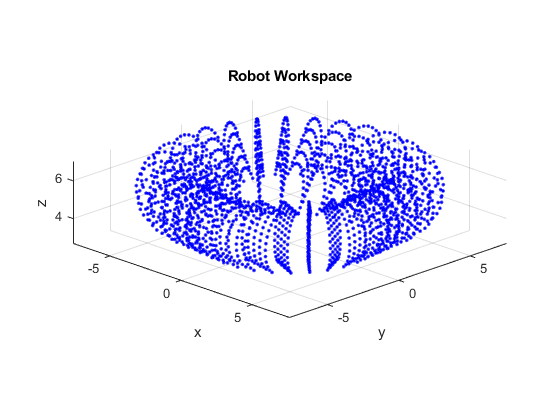


% Plot WS
figure
plot3(P(:,1),P(:,2),P(:,3),'.b');
xlabel('x');ylabel('y');zlabel('z');
title('Robot Workspace')
axis equal; grid on; view(45,20);

p.LineWidth = 3;
% set(gcf,'Visible','on')

## Inverse Kinematics

### Initial position test

figure
plot3(P0e_0(1),P0e_0(2),P0e_0(3),'*r')
hold on

Inverse kinematics:

Q_0 = DHinv(P0e_0,D,A,alpha);

argument = 5.9212e-16

count=0;
for i=1:2   
        P0(i,:)=DHdirect(Q_0(i,1),Q_0(i,2),Q_0(i,3));
    
    if count==0
        plot3(P0(i,1),P0(i,2),P0(i,3),'sg')
    else
        plot3(P0(i,1),P0(i,2),P0(i,3),'.b')
    end

    err(i) = norm(P0(i,:)-P0e_0');
    if err(i)<10^-10
        err(i)=0; 
    end
    count=count+1;
end
err

err =      0     0


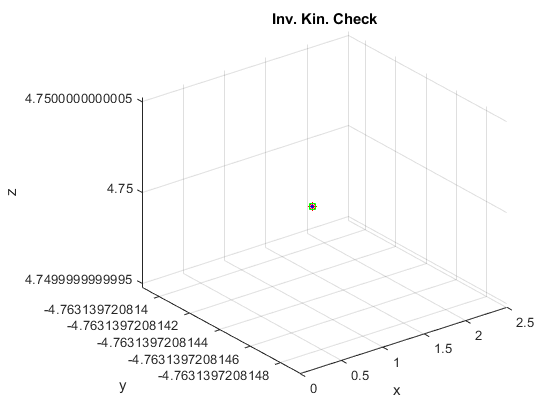

hold off; grid on;
xlabel('x'); ylabel('y'); zlabel('z')
title('Inv. Kin. Check')

% set(gcf,'Visible','on')

Check robot position

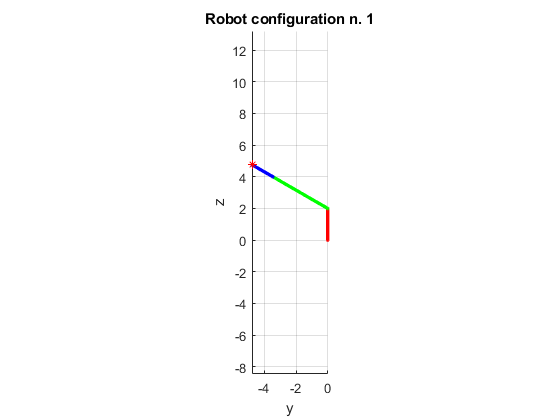

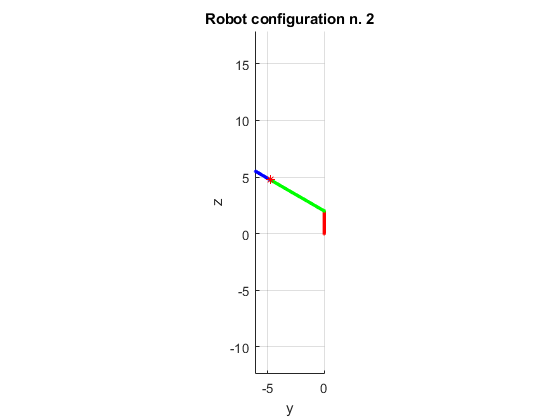

for i=1:size(Q_0,1)
    figure
    DH_plot_robot(Q_0(i,:),D,A,alpha,gcf,P0e_0)
    grid on
    axis equal
    view(90,0)
    xlabel('x'); ylabel('y'); zlabel('z')
    title(['Robot configuration n. ',num2str(i)])
%     set(gcf,'Visible','on')
end

### General position

Dati dei valori di q (Qi), ricavo il corrispondente punto (Pi) con la cinematica diretta.

Qi=[1.5*pi 3 pi/4]

Qi =     4.7124    3.0000    0.7854


Pi=DHdirect(Qi(1),Qi(2),Qi(3))'

Pi =    -6.4504   -1.1000    6.9489    1.0000


Partendo da un punto Pi, calcolo i valori di q corrispondenti con la cinematica inversa (Qf). Da Qf ricalcolo, poi, Pf con la cinematica diretta. 

Confronto Pf con Pi.

Qf = DHinv(Pi,D,A,alpha)

argument = 0.7071

Qf =    -1.5708    3.0000    0.7854
   -1.5708    5.1213    2.3562


for i=1:size(Qf,1)
    Pf(i,:)=DHdirect(Qf(i,1),Qf(i,2),Qf(i,3))';
    errP(i)=norm(Pf(i,:)-Pi);
    if errP(i)<10^-10
        errP(i)=0; 
    end 
end
Pf

Pf =    -6.4504   -1.1000    6.9489    1.0000
   -6.4504   -1.1000    6.9489    1.0000


errP

errP =      0     0


Confronto le configurazioni del robot per le diverse opzioni date da Qf.

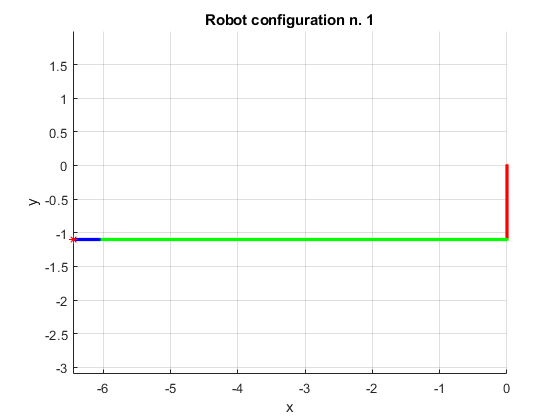

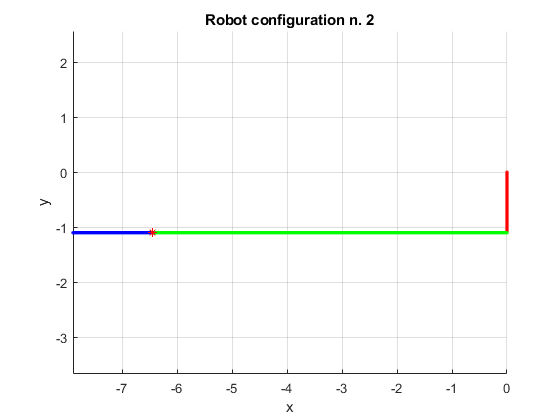

for i=1:size(Qf,1)
    figure
    DH_plot_robot(Qf(i,:),D,A,alpha,gcf,Pi)
    grid on
    axis equal
%     view(90,0)
    xlabel('x'); ylabel('y'); zlabel('z')
    title(['Robot configuration n. ',num2str(i)])
%     set(gcf,'Visible','on')
end